clear; clc; close all

Load a test image

impath = "C:\Users\Iñigo\OneDrive - Mondragon Unibertsitatea\BIOMEDIKA\MASTER\2nd Semester\ADV_IM_PROCESSING\PARKINSON_DRAWINGS\spiral\training\healthy"

impath = "C:\Users\Iñigo\OneDrive - Mondragon Unibertsitatea\BIOMEDIKA\MASTER\2nd Semester\ADV_IM_PROCESSING\PARKINSON_DRAWINGS\spiral\training\healthy"

imname = "\V04HE03.png"

imname = "\V04HE03.png"

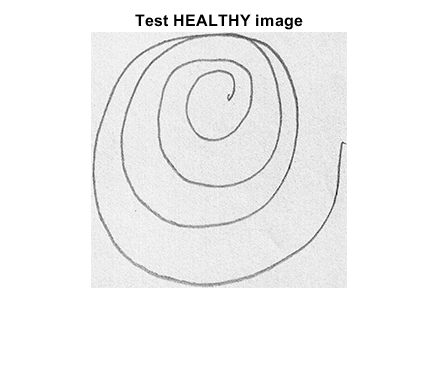

im = im2double(rgb2gray(imread(impath + imname)));
imshow(im, []); title('Test HEALTHY image')

[M,N] = size(im);

View image histogram

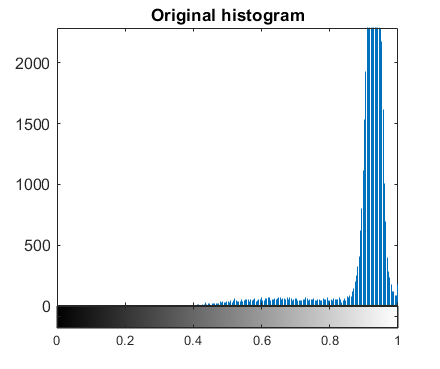

imhist(im);
title('Original histogram');

Apply Otsu's method thresholding to get the ROI of the stroke. Isolate the stroke.

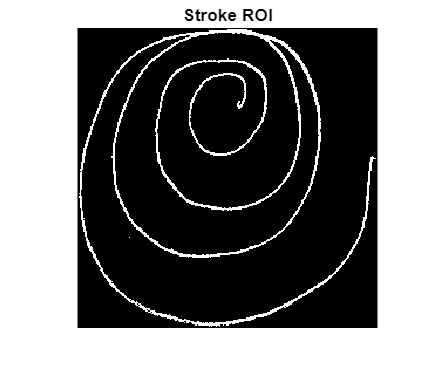

T = graythresh(im);
ROI = im < T;
imshow(ROI); title('Stroke ROI')

Get the skeleton of the image and prune it

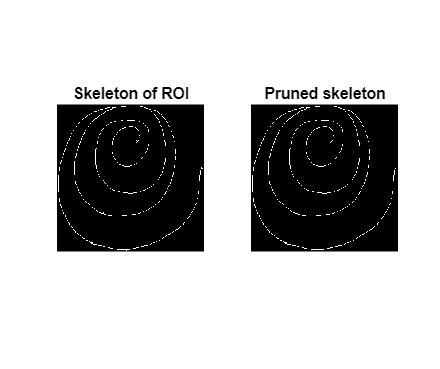

skel_im = bwmorph(ROI, 'skel', Inf);
subplot(121);imshow(skel_im); title('Skeleton of ROI')
pruned_skel_im = bwmorph(skel_im, 'spur', 3);
% Remove single, isolated pixels from the image
% temp
subplot(122);imshow(pruned_skel_im); title('Pruned skeleton')

Prepare for the region growing procedure:

Get a starting position

% First we need to get one of the starting points. Hit or miss. No matter
% which one we take and the order of growing, because we will look at the
% spectral information of the signal.

% Remove single pixels
pattern = zeros(3); pattern(2,2) = 1;
single_pixels = myhitnmiss(pruned_skel_im, pattern, 1); [spy, spx] = find(single_pixels);
pruned_skel_im(spy, spx) = 0;

% Find endpoints and get the outermost one (no particular reason, just to be
% consistent)
hits = bwmorph(pruned_skel_im, 'endpoints'); [endpy, endpx] = find(hits);

% Measure euclidean distance to center and take biggest (furthest point
% from center)
[M, N] = size(im);
C = round(0.5*[M, N]);
dists = sqrt((endpy-C(1)).^2 + (endpx-C(2)).^2); [~, biggest] = max(dists);
Y_init = endpy(biggest); X_init = endpx(biggest);


Start region growing.

target_im = zeros(M,N); target_im(Y_init, X_init) = 1;
dilater = strel('square', 3);

Xk = target_im;
i = 1;
canv_n = pruned_skel_im;
figure;
while (1)
    canv = canv_n;
    dil_point = imdilate(Xk, dilater);
    both_im = canv & dil_point;
    new_point = xor(Xk, both_im);
    canv_n = canv - both_im;
    imshow(canv_n); pause(0.001)
    if  isequal(canv, canv_n)%(i ~= 0 && Y_pts(i) == Y_pts(i-1) && X_pts(i) == X_pts(i-1))
        break;
    else
    Xk = new_point;
        [Y_pts(i), X_pts(i)] = find(new_point, 1); 
    end
    i = i + 1;
end

for cK = 1:length(X_pts)
    sig(cK) = im(Y_pts(cK), X_pts(cK));
end